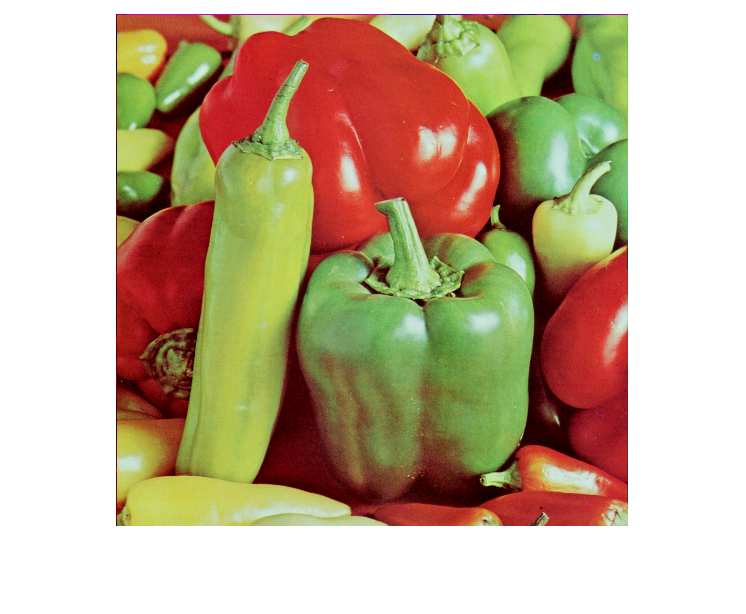

img = imread("../materials/PeppersRGB.tif");
img = double(img) / 255;
[M, N, C] = size(img);
imshow(img, [])

R = img(:, :, 1);
G = img(:, :, 2);
B = img(:, :, 3);

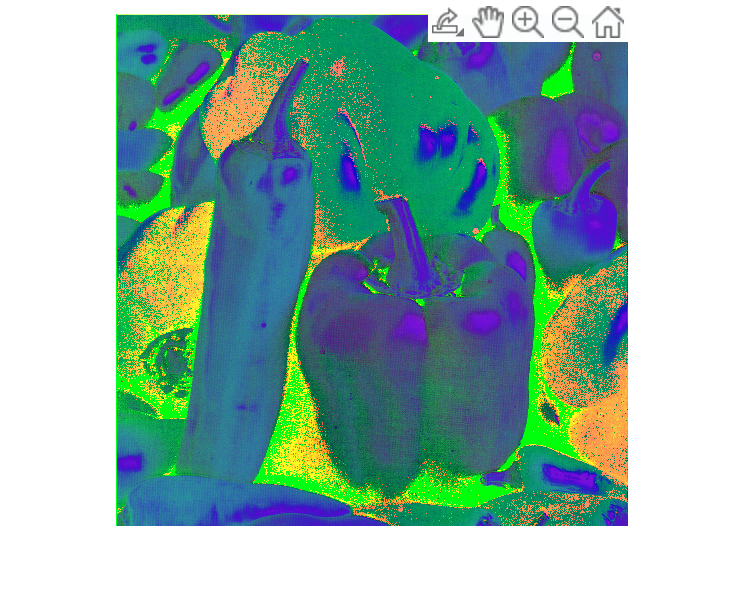

% RGB -> HSI
H = acosd((2*R-B-G)./(2*sqrt(((R-G).^2+(R-B).*(G-B))+1e-10)));
H(B>G) = 360-H(B>G);
H = real(H)/360;
S = 1 - 3*min(img, [], 3)./(R+G+B + 1e-3);
I = (R+G+B)/3;
HSI = zeros(size(img));
HSI(:,:,1) = H;
HSI(:,:,2) = S;
HSI(:,:,3) = I;
imshow(HSI, [])

% HSI -> RGB
H_ = H * 360;
H = H * 360;
H_(H>=120 & H<240) = H_(H>=120 & H<240) - 120;
H_(H>=240) = H_(H>=240) - 240;

X = I.*(1-S);
Y = I.*(1+S.*cosd(H_)./cosd(60-H_));
Z = 3.*I-(X+Y);

R = X;
G = Y;
B = Z;

R(H < 120) = Y(H < 120);
R(H >= 240) = Z(H >= 240);

G(H < 120) = Z(H < 120);
G(H >= 240) = X(H >= 240);

B(H < 120) = X(H < 120);
B(H >= 240) = Y(H >= 240);

RGB = zeros(size(img));
RGB(:,:,1) = R;
RGB(:,:,2) = G;
RGB(:,:,3) = B;

imshow(RGB,[])